answer = questdlg('Did you get the test email?','Test email check', 'Yes / Don''t care', 'No', 'Yes / Don''t care');
    switch answer
        case 'No'
            disp('Please check email settings to proceed.')
            return
    end

for dd = 1:length(data_files)
    clearvars -except dd *_dir user_email data_files
    cd([data_files(dd).folder '/' data_files(dd).name])



Confirm Intrinsics file for each day of flights

    answer = questdlg('Has the camera been calibrated?', 'Camera Calibration', 'Yes', 'No', 'Yes');
    switch answer
        case 'Yes'
            [temp_file, temp_file_path] = uigetfile(global_dir, 'Camera Parameters');
            load(fullfile(temp_file_path, temp_file)); clear temp_file*
        case 'No'
            disp('Please calibrate camera to proceed.')
            return
    end

Create data products and grid

## Define product type

answer = questdlg('Do you have a .mat Products file?', 'Product file', 'Yes', 'No', 'No');

switch answer
    case 'Yes'
        [temp_file, temp_file_path] = uigetfile(global_dir, 'Product file');
        load(fullfile(temp_file_path, temp_file)); clear temp_file*
        
        if ~exist('Products', 'var')
            disp('Please fill make Products file.')
            user_input_products
        end
    case 'No'
        user_input_products
end

yy =   -300  -250  -200  -150  -100   -50     0    50   100   150   200   250   300


Check how many set of images we need to extract - e.g. 2Hz images can be pulled from 10Hz, but 3Hz cannot

    info_Hz = unique([Products.frameRate]);  
    extract_Hz = max(info_Hz);
    for hh = 1:length(info_Hz)
        if rem(max(info_Hz), info_Hz(hh)) == 0
            sprintf('%i Hz data can be pulled from %i Hz data', info_Hz(hh), max(info_Hz))
        else
            sprintf('%i Hz data CANNOT be pulled from %i Hz data', info_Hz(hh), max(info_Hz))
            extract_Hz = [extract_Hz info_Hz(hh)];
        end
    end

ans = '2 Hz data can be pulled from 10 Hz data'

ans = '10 Hz data can be pulled from 10 Hz data'

Save all day info

    flights = dir([data_files(dd).folder '/' data_files(dd).name]); flights([flights.isdir]==0)=[]; flights(contains({flights.name}, '.'))=[]; flights(contains({flights.name}, 'GCP'))=[];
    save([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'],...
         'cameraParams*', 'extract_Hz', 'Products', 'flights')

Process each flight

    
    for ff = 1:length(flights)
        clearvars -except dd ff *_dir user_email data_files
        load([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'])
        
        odir = [flights(ff).folder '/' flights(ff).name '/'];
        oname = [data_files(dd).name '_' flights(ff).name];
        cd(odir) 
        if ~exist([odir '/Processed_data'], 'dir')
            mkdir 'Processed_data'
        end
   

Pull initial drone coordinates and which movies to process from metadata

        system(sprintf('exiftool -filename -CreateDate -Duration -CameraPitch -CameraYaw -CameraRoll -AbsoluteAltitude -RelativeAltitude -GPSLatitude -GPSLongitude -csv -c "%%.20f" %s/DJI_0* > %s/%s', odir, [odir 'Processed_data/'], [oname '.csv']));
        
        C = readtable(fullfile(odir, [oname '.csv']))
        format long
        % get indices of images and videos to extract from
        form = char(C.FileName);
        form = string(form(:,end-2:end));
        mov_id = find(form == 'MOV'); 
        jpg_id = find(form == 'JPG');
    
        % required: starting on full video 5:28 for DJI
        i_temp = find(C.Duration(mov_id) == duration(0,5,28)); mov_id(1:i_temp(1)-1)=[];
        i_temp = find(isnan(C.Duration(mov_id))); mov_id(i_temp)=[];
    
        % if image taken at beginning & end of flight - use beginning image
        if length(jpg_id) > 1;jpg_id = jpg_id(1); end
        % if no image taken, use mov_id
        if isempty(jpg_id); jpg_id = mov_id(1); end
    
        %  
        % pull RTK-GPS coordinates from image and change to Eastings/Northings
        % requires intg2012b and ll_to_utm codes (in basi
        lat = char(C.GPSLatitude(jpg_id));
        lat = str2double(lat(1:10));
        long = char(C.GPSLongitude(jpg_id));
        if long(end) == 'W'
            long = str2double(['-' long(1:11)]);
        else
            long = str2double(long(1:11));
        end
        [zgeoid_offset] = intg2012b(code_dir, lat,long);
        [UTMNorthing, UTMEasting, UTMZone] = ll_to_utm(lat, long);
        extrinsicsInitialGuess = [UTMEasting UTMNorthing C.RelativeAltitude(jpg_id)-zgeoid_offset deg2rad(C.CameraYaw(mov_id(1))+360) deg2rad(C.CameraPitch(mov_id(1))+90) deg2rad(C.CameraRoll(mov_id(1)))]; % [ x y z azimuth tilt swing]
        
    
        save(fullfile(odir, 'Processed_data', 'Inital_coordinates'), 'extrinsicsInitialGuess', 'UTMNorthing', 'UTMEasting', 'zgeoid_offset', 'jpg_id', 'mov_id', 'lat', 'long', 'C')

Extract 1st frame to use as example

        if ~exist([odir 'Processed_data/Initial_frame.jpg'], 'file')    
            system(['ffmpeg -ss 00:00:00 -i ' char(string(C.FileName(mov_id(1)))) ' -frames:v 1 -loglevel quiet -stats -qscale:v 2 Processed_data/Initial_frame.jpg']);
        end


Confirm whether distortion was on or off

        I = imread([odir 'Processed_data/Initial_frame.jpg']);
        if all( exist('cameraParams_distorted', 'var'), exist('cameraParams_undistorted', 'var') )
            J1 = undistortImage(I, cameraParams_distorted);
            J2 = undistortImage(I, cameraParams_undistorted);
            hFig = figure(1);clf
            montage({I, J1, J2}, 'Size', [1 3])
            text(200,-20, 'Original 1st frame', 'FontSize', 14)
            text(700,-20, 'Distortion Correction OFF', 'FontSize', 14)
            text(1200,-20, 'Distortion Correction ON', 'FontSize', 14)
            
            [ind_distortion,tf] = listdlg('ListString',[{'Distorted (Off)'}, {'Undistorted (On)'}, {'Recalibrate Camera'}], 'SelectionMode','single', 'InitialValue',2, 'PromptString', {'Distortion correction On/Off?'});
            if ind_distortion == 1
                cameraParams = cameraParams_distorted;
                clf;imshowpair(I,J1, 'montage'); print(gcf, '-dpng', [odir 'Processed_data/undistortImage.png'])
            elseif ind_distortion == 2
                cameraParams = cameraParams_undistorted;
                clf;imshowpair(I,J2, 'montage'); print(gcf, '-dpng', [odir 'Processed_data/undistortImage.png'])
            elseif ind_distortion == 3
                disp('Please recalibrate camera or check that correct intrinsics file is used.')
                return
            end
        else
            J1 = undistortImage(I, cameraParams);
            hFig = figure(1);clf
            imshowpair(I,J1, 'montage')
            
            [ind_distortion,tf] = listdlg('ListString',[{'Correctly calibrated'}, {'Recalibrate Camera'}], 'SelectionMode','single', 'InitialValue',1, 'PromptString', {'Is the camera corrected calibrated?'});
            if ind_distortion == 1
                clf;imshowpair(I,J1, 'montage'); print(gcf, '-dpng', [odir 'Processed_data/undistortImage.png'])
            elseif ind_distortion == 2
                disp('Please recalibrate camera or check that correct intrinsics file is used.')
                return
            end

        end

        intrinsics(1) = cameraParams.ImageSize(2);            % Number of pixel columns
        intrinsics(2) = cameraParams.ImageSize(1);            % Number of pixel rows
        intrinsics(3) = cameraParams.PrincipalPoint(1);         % U component of principal point  
        intrinsics(4) = cameraParams.PrincipalPoint(2);          % V component of principal point
        intrinsics(5) = cameraParams.FocalLength(1);         % U components of focal lengths (in pixels)
        intrinsics(6) = cameraParams.FocalLength(2);         % V components of focal lengths (in pixels)
        intrinsics(7) = cameraParams.RadialDistortion(1);         % Radial distortion coefficient
        intrinsics(8) = cameraParams.RadialDistortion(2);         % Radial distortion coefficient
        intrinsics(9) = cameraParams.RadialDistortion(3);         % Radial distortion coefficient
        intrinsics(10) = cameraParams.TangentialDistortion(1);        % Tangential distortion coefficients
        intrinsics(11) = cameraParams.TangentialDistortion(2);        % Tangential distortion coefficients
        
        if ind_distortion == 2
            intrinsics(7:11) = 0; % no distortion (if distortion correction on)
        end

        save(fullfile(odir, 'Processed_data', [oname '_IO']), 'intrinsics')



Check grid  - NEED TO FIX COORDINATES - COMPARE TO DEFAULT

    load(fullfile(odir, 'Processed_data', 'Inital_coordinates.mat'), 'extrinsicsInitialGuess')
    load(fullfile(odir, 'Processed_data', [oname '_IO']), 'intrinsics')
    load([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'])
    I=imread([odir 'Processed_data/Initial_frame.jpg']);
    %%
    ids_grid = find(contains(extractfield(Products, 'type'), 'Grid'));
    ids_xtransect = find(contains(extractfield(Products, 'type'), 'xTransect'));
    ids_ytransect = find(contains(extractfield(Products, 'type'), 'yTransect'));

GRID

        for pp = ids_grid
        gridChangeIndex = 0; % check grid
            while gridChangeIndex == 0
                [y2,x2, ~] = ll_to_utm(Products(pp).lat, Products(pp).lon);
                localExtrinsics = localTransformExtrinsics([x2 y2], -(270-Products(pp).angle), 1, extrinsicsInitialGuess);
                
                if Products(pp).xlim(1) < 0; Products(pp).xlim(1) = -Products(pp).xlim(1); end
                ixlim = x2 - Products(pp).xlim;
                
                if Products(pp).ylim(1) > 0; Products(pp).ylim(1) = -Products(pp).ylim(1); end
                if Products(pp).ylim(2) < 0; Products(pp).ylim(2) = -Products(pp).ylim(2); end
                iylim = y2 + Products(pp).ylim;
        
                [iX, iY]=meshgrid(ixlim(1):Products(pp).dx:ixlim(2),iylim(1):Products(pp).dy:iylim(2));
                
                % DEM stuff
                if isempty(Products(pp).z); iz=0; else; iz = Products(pp).z; end
                iZ=iX*0+iz;
                
                X=iX; Y=iY; Z=iZ; 
                [localX, localY]=localTransformEquiGrid([x2 y2], 270-Products(pp).angle,1,iX,iY); 
                localZ=localX.*0+iz; 
                
                [Ir]= imageRectifier(I,intrinsics,extrinsicsInitialGuess,X,Y,Z,1);
                subplot(2,2,[2 4])
                title('World Coordinates')
                
                %if all([x2 y2] ~= [0,0], 270-Products(pp).angle ~= 0)
                    [localIr]= imageRectifier(I,intrinsics,localExtrinsics,localX,localY,localZ,1);
                
                    subplot(2,2,[2 4])
                    title('Local Coordinates')
                    print(gcf,'-dpng',[odir 'Processed_data/' oname '_' char(string(pp)) '_Grid_Local.png' ])
                %else
                %    print(gcf,'-dpng',[odir 'Processed_data/' oname '_Grid_World.png' ])
                %end
        
                answer = questdlg('Happy with rough grid projection?', ...
                     'Rough grid projection',...
                     'Yes', 'No', 'Yes');
        
                switch answer
                    case 'Yes'
                        gridChangeIndex = 1;
                    case 'No'
                       disp('Please change grid.')
                       info = double(string(inputdlg({'Frame Rate (Hz)', 'Offshore cross-shore extent (m from Origin)', 'Onshore cross-shore extent (m from Origin)', ...
                                     'Southern Alongshore extent (m from Origin)', 'Northern Alongshore extent (m from Origin)',...
                                     'dx', 'dy', 'z elevation (tide level in relevant datum - leave blank if you want to use a DEM)'})));
                        
                       info = abs(info); % making everything +meters from origin
                    
                        % check that there's a value in all the required fields
                        if find(isnan(info)) ~= 8
                            disp('Please fill out all boxes (except z elevation if necessary)')
                            info = double(string(inputdlg({'Frame Rate (Hz)', 'Offshore cross-shore extent (m from Origin)', 'Onshore cross-shore extent (m from Origin)', ...
                                         'Southern Alongshore extent (m from Origin)', 'Northern Alongshore extent (m from Origin)',...
                                         'dx', 'dy', 'z elevation (tide level in relevant datum - leave blank if you want to use a DEM)'})));
                            info = abs(info); % making everything +meters from origin
                        end
                        
                        if info(1) > 30
                            disp('Maximum frame rate is 30Hz - Please choose a different frame rate.')
                            info(1) = double(string(inputdlg({'Frame Rate (Hz)'})));
                        end
                        Products(pp).frameRate = info(1);
            
                        Products(pp).xlim = [info(2) -info(3)]; % offshore limit is negative meters
                        if Products(pp).angle < 180 % East Coast
                            Products(pp).ylim = [-info(5) info(4)]; % -north +south
                        elseif Products(pp).angle > 180 % West Coast
                            Products(pp).ylim = [-info(4) info(5)]; % -south +north
                        end
                        Products(pp).dx = info(6);
                        Products(pp).dy = info(7);
                        if ~isnan(info(8))
                            Products(pp).z = info(8);
                        else
                            % PULL IN DEM
                        end
                end % check answer
            end % check gridCheckIndex
        end % for pp = 1:length(ids_grid)


xTRANSECT

    if ~isempty(ids_xtransect)
        figure
        hold on
        imshow(I)
        hold on
        title('Timestack')
        jj=0
        for pp = ids_xtransect
            jj=jj+1;
            [y2,x2, ~] = ll_to_utm(Products(pp).lat, Products(pp).lon);
            
            if Products(pp).xlim(1) < 0; Products(pp).xlim(1) = -Products(pp).xlim(1); end
            ixlim = x2 - Products(pp).xlim;
            iy = y2 + Products(pp).y;
        
            X = [ixlim(1):Products(pp).dx:ixlim(2)]';
            Y = X.*0+iy;
            Z = X.*0;
            xyz = cat(2,X(:), Y(:), Z(:));
        
            [UVd] = xyz2DistUV(intrinsics, extrinsicsInitialGuess,xyz);
                
            UVd = reshape(UVd,[],2);
            plot(UVd(:,1),UVd(:,2),'*')
            xlim([0 intrinsics(1)])
            ylim([0  intrinsics(2)])
        
            le{jj}= [Products(pp).type ' - y = ' char(string(Products(pp).y)) 'm'];
           
        end % for pp = 1:length(ids_xtransect)
        legend(le)
        answer = questdlg('Happy with rough transect numbers?', ...
                     'Transect Numbers',...
                     'Yes', 'No', 'Yes');
        switch answer
            case 'Yes'
                gridChangeIndex = 1;
            case 'No'
               disp('Please change new transect numbers.')
               define_product_type
        end
        
        print(gcf,'-dpng',[odir 'Processed_data/' oname '_xTransects.png' ])
    end
        

yTRANSECT - NEED TO CHECK

    if ~isempty(ids_ytransect)
        figure
        hold on
        imshow(I)
        hold on
        title('yTransect')
        jj=0
        for pp = ids_ytransect
            jj=jj+1;
            [y2,x2, ~] = ll_to_utm(Products(pp).lat, Products(pp).lon);
            
            if Products(pp).ylim(1) > 0; Products(pp).ylim(1) = -Products(pp).ylim(1); end
            if Products(pp).ylim(2) < 0; Products(pp).ylim(2) = -Products(pp).ylim(2); end
            iylim = y2 + Products(pp).ylim;
        
            ix = x2 + Products(pp).x;
        
            Y = [iylim(1):Products(pp).dy:iylim(2)]';
            X = Y.*0+ix;
            Z = Y.*0;
            xyz = cat(2,X(:), Y(:), Z(:));
        
            [UVd] = xyz2DistUV(intrinsics, extrinsicsInitialGuess,xyz);
                
            UVd = reshape(UVd,[],2);
            plot(UVd(:,1),UVd(:,2),'*')
            xlim([0 intrinsics(1)])
            ylim([0  intrinsics(2)])
        
            le{jj}= [Products(pp).type ' - x = ' char(string(Products(pp).x)) 'm'];
           
        end % for pp = 1:length(ids_xtransect)
        legend(le)
        answer = questdlg('Happy with rough transect numbers?', ...
                     'Transect Numbers',...
                     'Yes', 'No', 'Yes');
        switch answer
            case 'Yes'
                gridChangeIndex = 1;
            case 'No'
               disp('Please change new transect numbers.')
               define_product_type
        end
        print(gcf,'-dpng',[odir 'Processed_data/' oname '_yTransects.png' ])
    end

Send email with images

    7 image files read


C = 7×11 table
                                              SourceFile                                                   FileName              CreateDate           Duration    CameraPitch    CameraYaw    CameraRoll    AbsoluteAltitude    RelativeAltitude             GPSLatitude                      GPSLongitude         
    _______________________________________________________________________________________________    ________________    _______________________    ________    ___________    _________    __________    ________________    ________________    _____________________________    ______________________________

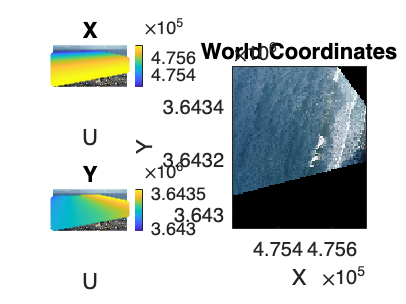

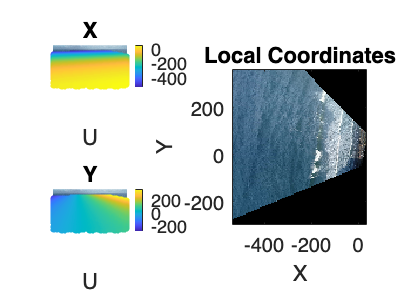

jj =      0


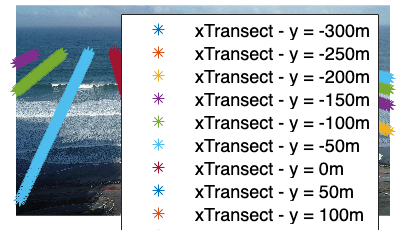

grid_text = 1×2 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475831.66, 3643235.46, 66.52, 5.05, 1.22, 0.00'}


grid_text = 1×3 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475831.66, 3643235.46, 66.52, 5.05, 1.22, 0.00'}    {'Extract data at 10 Hz. '}


grid_text = 1×4 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475831.66, 3643235.46, 66.52, 5.05, 1.22, 0.00'}    {'Extract data at 10 Hz. '}    {'Products to produce:'}


    8 image files read


C = 8×11 table
                                              SourceFile                                                   FileName              CreateDate           Duration    CameraPitch    CameraYaw    CameraRoll    AbsoluteAltitude    RelativeAltitude             GPSLatitude                      GPSLongitude         
    _______________________________________________________________________________________________    ________________    _______________________    ________    ___________    _________    __________    ________________    ________________    _____________________________    ______________________________

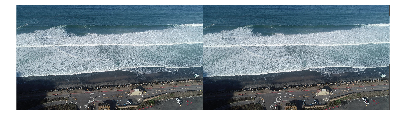

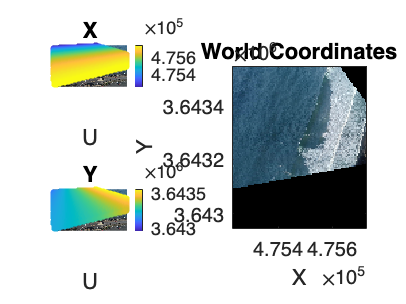

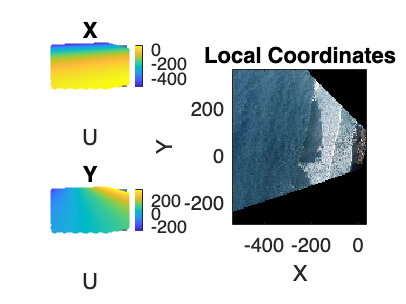

jj =      0


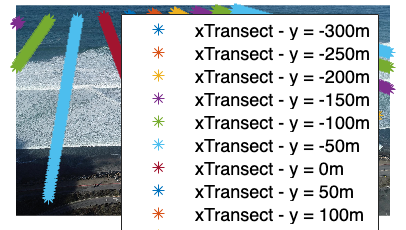

grid_text = 1×2 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475829.13, 3643229.68, 88.08, 5.09, 1.06, 0.00'}


grid_text = 1×3 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475829.13, 3643229.68, 88.08, 5.09, 1.06, 0.00'}    {'Extract data at 10 Hz. '}


grid_text = 1×4 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475829.13, 3643229.68, 88.08, 5.09, 1.06, 0.00'}    {'Extract data at 10 Hz. '}    {'Products to produce:'}


        clear grid_text grid_plot
        grid_text{1} = sprintf('Lat / Long = %.2f / %.2f, Angle = %.2f deg', Products(1).lat, Products(1).lon, Products(1).angle);
        grid_text{2} = sprintf('Initial Extrinsics Guess: %.2f, %.2f, %.2f, %.2f, %.2f, %.2f', extrinsicsInitialGuess)
        grid_text{3} = sprintf('Extract data at %i Hz. ', extract_Hz)
        grid_text{4} = sprintf('Products to produce:')
        
        grid_plot{1} = [odir 'Processed_data/undistortImage.png'];
        ids_grid = find(contains(extractfield(Products, 'type'), 'Grid'));
        ids_xtransect = find(contains(extractfield(Products, 'type'), 'xTransect'));
        ids_ytransect = find(contains(extractfield(Products, 'type'), 'yTransect'));
        
        for pp = ids_grid
            grid_text{length(grid_text)+1} = sprintf('Type = %s, frameRate = %i Hz, xlim = [%i %i], ylim = [%i %i], (dx,dy) = [%.1f %.1f] m', Products(pp).type, Products(pp).frameRate, Products(pp).xlim(1), Products(pp).xlim(2), Products(pp).ylim(1), Products(pp).ylim(2), Products(pp).dx, Products(pp).dy);
            grid_plot{length(grid_plot)+1} = [odir 'Processed_data/' oname '_' char(string(pp)) '_Grid_Local.png' ];
        end
        for pp = ids_xtransect
            grid_text{length(grid_text)+1} = sprintf('Type = %s, frameRate = %i Hz, xlim = [%i %i], y = %.1f m, dx = %.1f m', Products(pp).type, Products(pp).frameRate, Products(pp).xlim(1), Products(pp).xlim(2), Products(pp).y, Products(pp).dx);
        end
        for pp = ids_ytransect
            grid_text{length(grid_text)+1} = sprintf('Type = %s, frameRate = %i Hz, x = %.1f m, ylim = [%i %i], dy = %.1f m', Products(pp).type, Products(pp).frameRate, Products(pp).x, Products(pp).ylim(1), Products(pp).ylim(2), Products(pp).dy);
        end
        if ~isempty(ids_xtransect)
            grid_plot{length(grid_plot)+1} = [odir 'Processed_data/' oname '_xTransects.png' ];
        end
        if ~isempty(ids_ytransect)
            grid_plot{length(grid_plot)+1} = [odir 'Processed_data/' oname '_yTransects.png' ];
        end
     

   
    sendmail(user_email{2}, [oname '- Input Data'], ...
        grid_text, grid_plot)


       % close all
    end % for ff = 1:length(flights)
end % for dd = 1:length(data_files)
